# **PageRank : Script e Test dell'Algoritmo**

#### **Il seguente script mostra l'utilizzo dell'Algoritmo di PageRank implementato andando a leggere la matrice di Adiacenze G e un array U di URL da un file esterno o adoperando la funzione *****"surfer" .***

### Descrizione

**Lo script calcola:**

- **Il PageRank della Matrice G di Adiacenza**

- **Mostra la sparsità della stessa attraverso un grafico**

- **Mostra i primi 15 risultati in ordine decrescente in termini di Outdegree e Indegree**

- **Ricava un grafico a barre dei PageRank calcolati**

- **Mostra un Grafo orientato dove i nodi rappresentano le pagine web con rank maggiore della media dei rank.**

**Oltre a ciò vengono effettuati dei casi di test sulla correttezza dell'algoritmo implementato e sulla performance dello stesso prendendo di riferimento la funzione *****"centrality" *****del MATLAB. Infine vengono effettuati dei casi di test sulla robustezza dell'algoritmo.**

# Utilizzo

**Per prima cosa bisogna pulire il workspace e caricare la matrice G e l'array U da un file esterno. Utilizziamo lo script *****"surfer"***

clear
[U,G] = surfer('https://www.apple.com/it/',100);
%load mathwork200.mat
%load repubblica.mat

**In alternativa alla funzione surfer è possibile caricare uno tra i file "mathwork200.mat" e "repubblica.mat" che contengono già la matrice G e il vettore U.**

### **Struttura della Matrice G**

**Per visualizzare la struttura della matrice G viene utilizzato il comando "spy" che mostra un grafico della sparsità della matrice.**

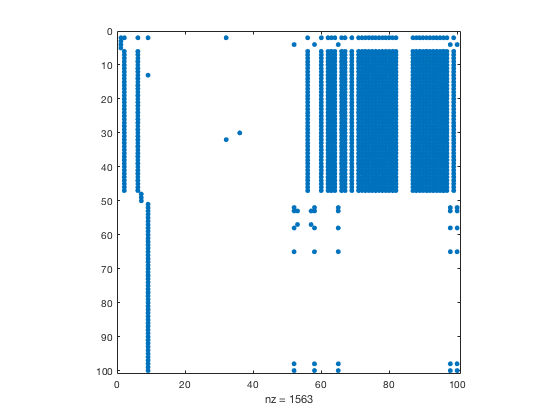

spy(G)

### Grafo Associato della Matrice G

**In allegato alla struttura della matrice, viene ricavato il grafo associato ad essa. Ogni nodo del grafo rappresenta l'identificativo della pagina e ogni arco i collegamenti (URL) tra loro.**

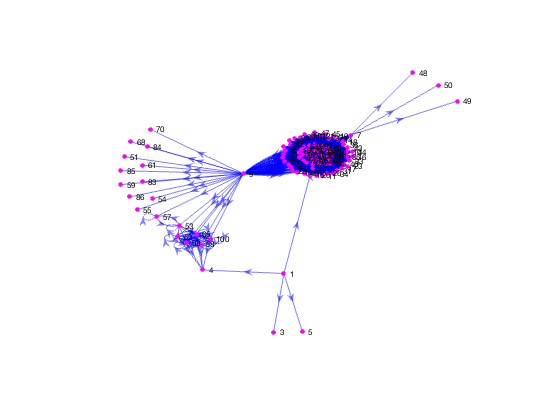

grafo = digraph(G');
plot(grafo,'NodeColor','m','EdgeColor','b','Layout','force');
axis off

### Uso dell'Algoritmo di PageRank

**Una volta ottenuta la matrice G ed il vettore U è possibile ottenere dall'Algoritmo di PageRank, il vettore dei Rank delle pagine associati agli Outdegree e Indegree delle stesse per poi associarle al grafo in sovraimpressione.**

***N.B : Per informazioni sull'Algoritmo di PageRank si faccia riferimento alla documentazione specificata nel file "Documentazione_PageRank.pdf"***

[R,Outdeg,Indeg] = PageRank(G);
grafo.Nodes.PageRank = R;
grafo.Nodes.InDegree = Indeg;
grafo.Nodes.OutDegree = Outdeg;

#### Tabella degli Outdegree e Indegree

**Mostriamo dunque di seguito i primi 15 Rank prodotti dall'algoritmo in senso decrescente, in accoppiata ai corrispettivi OutDegree, InDegree e agli Identificativi nel Grafo.**

[R,indice] = sort(R,'descend');
siti_web = U(indice(1:15));
id = indice(1:15);
ranks = R(1:15);
outdegrees = Outdeg(indice(1:15));
indegrees = Indeg(indice(1:15));
table(id,ranks,outdegrees,indegrees,'RowNames',siti_web)

ans = 15×4 table
                                                          id      ranks      outdegrees    indegrees
                                                          ___    ________    __________    _________

    http://purl.org/dc/elements/1.1                        53    0.075788         1            7    
    http://purl.org/dc/elements/1.1/identifier             57    0.070456         1            2    
    http://ogp.me/ns#                                       2    0.020055        42           36    
    http://groups.google.com/group/open-graph-protocol     30    0.019046         0           35    
    http://schema.org                                       4     0.01698         0            6    
    http://xmlns.com/foaf/0.1                 

#### Istogramma dei PageRank

**Di seguito mostriamo un istogramma dei PageRank ottenuti dall'Algoritmo**

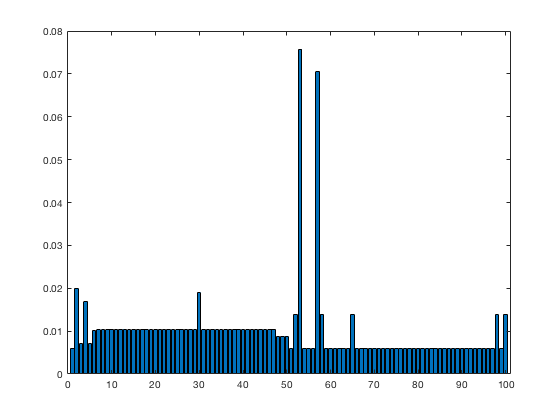

bar(grafo.Nodes.PageRank)

#### Sottografo dei PageRank

**Associato all'istogramma, mostriamo il sottografo dei Nodi tali che essi abbiano PageRank maggiore della media dei PageRank.**

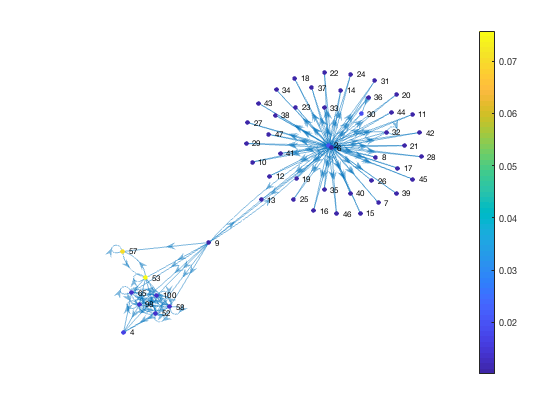

condition = find(grafo.Nodes.PageRank > mean(grafo.Nodes.PageRank));
sotto_grafo = subgraph(grafo,condition);
plot(sotto_grafo,'NodeLabel',condition,'NodeCData',sotto_grafo.Nodes.PageRank,'Layout','force');
colorbar;
axis off;

# Valutazione Performance e Test di Correttezza

**Per valutare la correttezza dell'algoritmo implementato viene effettuata una valutazione delle performance rispetto alla funzione "centrality" del MATLAB, mostrando in una tabella i risultati ottenuti.**

Valuta_Performance()

ans = 15×4 table
                                                          ID       rank      outdegree    indegree
                                                          ___    ________    _________    ________

    http://purl.org/dc/elements/1.1                        53    0.075788        1            7   
    http://purl.org/dc/elements/1.1/identifier             57    0.070456        1            2   
    http://ogp.me/ns#                                       2    0.020055       42           36   
    http://groups.google.com/group/open-graph-protocol     30    0.019046        0           35   
    http://schema.org                                       4     0.01698        0            6   
    http://xmlns.com/foaf/0.1                         

# Test di Robustezza

**Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 8 ,implementati in una classe definita dal matlab *****matlab.unittest.TestCase*****. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.**

**Di seguito sono mostrati  i casi di test  più rilevanti che sono stati effettuati ,rispettando la precedenza tra essi.**

## Test case 1

Verifica l'errore nel caso in cui la matrice G è non sparsa.

## Input


$$G=\mathrm{rand}\left(10\right)$$


## Test case 2

Verifica l'errore nel caso in cui la matrice G è sparsa ma non quadrata.

## Input


$$G=\mathrm{rand}\left(10,15\right)$$


## Test case 3

Verifica l'errore nel caso in cui la matrice G non è logica.

## Input


$$G=\mathrm{round}\left(\mathrm{sprand}\left(10,10,0\ldotp 2\right)*10\right)$$


## Test case 4

Verifica il warning nel caso in cui la matrice G contenga dei selfloops.

## Input


$$G=\mathrm{logical}\left(G+\mathrm{speye}\left(\mathrm{size}\left(G\right)\right)\right)$$


### Esecuzione Test Suite

Vengono effettuati in modo automatizzato i casi di test sugli input definiti in precedenza

results = runtests('CasiTest.m')

Running CasiTest
.......
Done CasiTest
__________



results =   1×7 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   7 Passed, 0 Failed, 0 Incomplete.
   0.064495 seconds testing time.


Riportiamo su una tabella i casi di test effettuati

table(results)

ans = 7×6 table
            Name            Passed    Failed    Incomplete    Duration       Details   
    ____________________    ______    ______    __________    _________    ____________

    'CasiTest/TestCase1'    true      false       false       0.0083891    [1×1 struct]
    'CasiTest/TestCase2'    true      false       false       0.0099731    [1×1 struct]
    'CasiTest/TestCase3'    true      false       false       0.0064264    [1×1 struct]
    'CasiTest/TestCase4'    true      false       false       0.0068691    [1×1 struct]
    'CasiTest/TestCase5'    true      false       false        0.010113    [1×1 struct]
    'CasiTest/TestCase6'    true      false       false       0.0061356    [1×1 struct]
    'CasiTest/TestCase7'    true      false       false        0.016589    

In particolare l'ultimo caso di test effettuato verifica il funzionamento dell'algoritmo nel caso in cui sono presenti self loops, che indicano pagine che si autoreferenziano. Queste non devono essere considerate nel calcolo del rank e appunto il caso di test genererà un warning apposito. Riportiamo per completezza il comportamento del suddetto caso di test.

results = runtests('CasiTest.m','ProcedureName','TestCase7')

Running CasiTest
.
Done CasiTest
__________



results =   TestResult with properties:

          Name: 'CasiTest/TestCase7'
        Passed: 1
        Failed: 0
    Incomplete: 0
      Duration: 0.0173
       Details: [1×1 struct]

Totals:
   1 Passed, 0 Failed, 0 Incomplete.
   0.017324 seconds testing time.


## Riferimenti               

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

- Misura di Performance in Matlab [https://it.mathworks.com/help/matlab/performance-and-memory.html](https://it.mathworks.com/help/matlab/performance-and-memory.html)

- PageRank - Wikipedia [https://it.wikipedia.org/wiki/PageRank](https://it.wikipedia.org/wiki/PageRank)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**